%% REFERENCE
% Consensus Equilibrium for Super-Resolution and Extreme-Scale CT SC %19, November 17–22, 2019, Denver, CO, USA


%% CE-MBIR Equation
% Algorithm 2 Consensus Equilibrium MBIR
% INPUT: Measurements y and matrix A partitioned in any order.
% LOCAL: wi : a temporary copy for vi . ui : input change to proximal
% map function, Fi (x). Other variables are the same as in
% Algorithm 1.
% OUTPUT: x: the consensus HR solution.
% 1: Initialize x, vi , wi , and ui
% 2: while x , vi , i = 1, 2, ...,G do
% 3: for each subset i from 1 to G do in parallel
% 4: vi ← argminvi Fi (x + ui )
% 5: (w′)i ←wi
% 6: wi ← (2vi − x − ui )
% 7: wi ← ρwi +􀀀1 − ρ�(w′)i , 0 ≤ ρ ≤ 1
% 8: end for
% 9: x ← Average(w1, · · · ,wG)
% 10: for each subset i from 1 to G do in parallel
% 11: ui ←x − wi
% 12: end for
% 13: end while
%% 
clear ;

isgpu   = true;


addpath(genpath('./utilities/'));
addpath(genpath('./denoisers/'));

#### SYSTEM SETTING


N       = 512;
ANG     = 180;

G       = 3;  % Number of subsets
VIEW_F    = 360;
VIEW    = 360/G;
THETA   = zeros(G,VIEW);
Offset  = zeros(1,G);

THETA_F   = linspace(0, ANG, VIEW_F + 1);   THETA_F(end) = [];

A_F       = @(x) radon(x, THETA_F);
% AT_F      = @(y) iradon(y, THETA_F, 'none', N)/(pi/(2*length(THETA)));
AINV_F    = @(y) iradon(y, THETA_F, N);

denoiser=@wrapper_TV;

A       = cell(1,G);
AT      = cell(1,G);
AINV    = cell(1,G);

for i = 1 : G
    
    Offset(i)   = (i-1)* (ANG/G/VIEW);
    THETA(i,:)  = linspace(0 + Offset(i), ANG - ANG/VIEW + Offset(i), VIEW);  % THETA(i,end) = [];
    A{i}        = @(x) radon(x, THETA(i,:));
    AT{i}       = @(y) iradon(y, THETA(i,:), 'none', N)/(pi/(2*length(THETA(i,:))));
    AINV{i}     = @(y) iradon(y, THETA(i,:), N);

end


#### DATA GENERATION


load('XCAT512.mat');
x       = imresize(double(XCAT512), [N, N]);
p       = cell(1,G);
pn      = cell(1,G);
y       = cell(1,G);
v       = cell(1,G);
% v       = cell(1,G);

p_F     = A_F(x);
x_full  = AINV_F(p_F);
i0          = 5e4;

for i = 1 : G

    p{i}        = A{i}(x);
    % x_full    = AINV(p);
    
    %% LOW-DOSE SINOGRAM GENERATION
    
    pn{i}       = exp(-p{i});
    pn{i}       = i0.*pn{i};
    pn{i}       = poissrnd(pn{i});
    pn{i}       = max(-log(max(pn{i},1)./i0),0);
    
    pn_F       = exp(-p_F);
    pn_F       = i0.*pn_F;
    pn_F       = poissrnd(pn_F);
    pn_F       = max(-log(max(pn_F,1)./i0),0);
    
    y{i}        = pn{i};
    y_F         = pn_F;
    
    %% Algebraic Reconstruction Technique (ART) INITIALIZATION
    v{i}        = AINV{i}(y{i});
    v_F         = AINV_F(y_F);

end

x0          = v{1};
alpha      = 1;
niter       = 2e1;
tol         = 1e-8;
bpos        = true;
lambda       = 1/sqrt(i0);
sigma2      = G;
rho         = 0.1;

#### RUN Algebraic Reconstruction Technique (ART)


if isgpu
    y{i} = gpuArray(y{i});
    x0 = gpuArray(x0);
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).
> In parallel.internal.pool.deserialize (line 33)
In parallel.internal.pool.deserializeFunction (line 17)
In remoteParallelFunction (line 29)
> In parallel.internal.pool.deserialize (line 33)
In parallel.internal.pool.deserializeFunction (line 17)
In remoteParallelFunction (line 29)

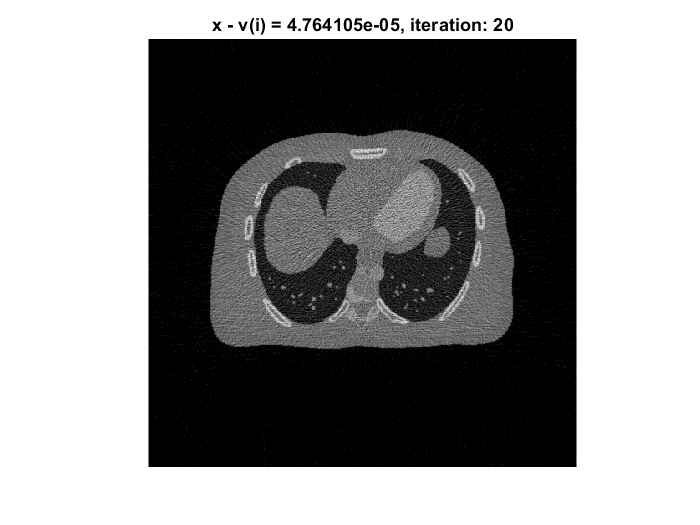


 tic
 
x_art   = CE_MBIR_2(A,AT,y,x0,G,denoiser,lambda,alpha,sigma2,rho,tol,niter,bpos);

t2 = toc

t2 = 88.7266

#### CALCULATE QUANTIFICATION FACTOR



x_low       = max(v_F, 0);
x_art       = max(x_art, 0);
nor         = max(x(:));

mse_x_low   = immse(x_low./nor, x./nor);
mse_x_art   = immse(x_art./nor, x./nor);

psnr_x_low  = psnr(x_low./nor, x./nor);
psnr_x_art  = psnr(x_art./nor, x./nor);

ssim_x_low  = ssim(x_low./nor, x./nor);
ssim_x_art  = ssim(x_art./nor, x./nor);


%% DISPLAY
wndImg  = [0, 0.03];
wndPrj  = [0, 6];

figure(1);
colormap(gray(256));

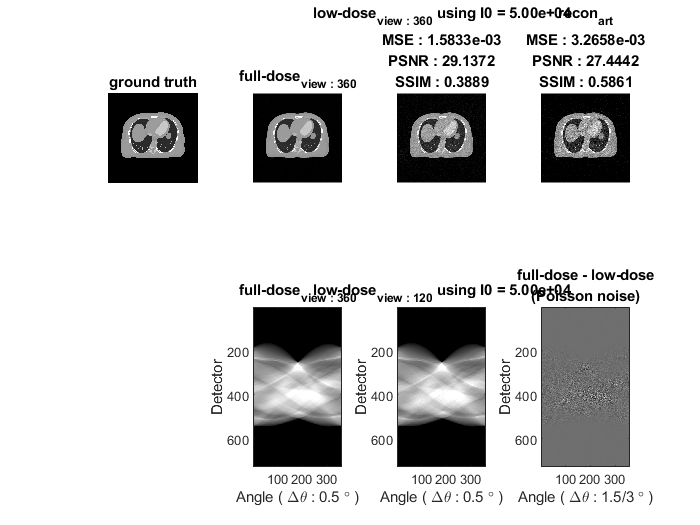


% suptitle('Algebraic Reconstruction Technique');
subplot(241);   imagesc(x,      wndImg);    axis image off;     title(['ground truth']);

subplot(242);   imagesc(x_full, wndImg);    axis image off;     title(['full-dose_{view : ', num2str(VIEW_F) '}']);
subplot(246);   imagesc(p_F, wndPrj);         xlabel(['Angle ( \Delta\theta : ' num2str(ANG/VIEW_F) ' \circ )']);   ylabel('Detector'); title(['full-dose_{view : ', num2str(VIEW_F) '}']);

subplot(243);   imagesc(v_F,  wndImg);    axis image off;     title({['low-dose_{view : ', num2str(VIEW_F) '}' ' using I0 = ' num2str(i0, '%.2e') ], ['MSE : ' num2str(mse_x_low, '%.4e')], ['PSNR : ' num2str(psnr_x_low, '%.4f')], ['SSIM : ' num2str(ssim_x_low, '%.4f')]});
subplot(247);   imagesc(y_F,  wndPrj);        xlabel(['Angle ( \Delta\theta : ' num2str(ANG/VIEW_F) ' \circ )']);   ylabel('Detector'); title(['low-dose_{view : ', num2str(VIEW) '} using I0 = ' num2str(i0, '%.2e')]);

subplot(244);   imagesc(x_art,  wndImg);    axis image off;     title({['recon_{art}'], ['MSE : ' num2str(mse_x_art, '%.4e')], ['PSNR : ' num2str(psnr_x_art, '%.4f')], ['SSIM : ' num2str(ssim_x_art, '%.4f')]});
subplot(248);   imagesc(y_F - p_F);             xlabel( [ 'Angle ( \Delta\theta : ' num2str(ANG/VIEW) '/' num2str(G)  ' \circ )' ] );   ylabel('Detector'); title({['full-dose - low-dose'],'(Poisson noise)'});